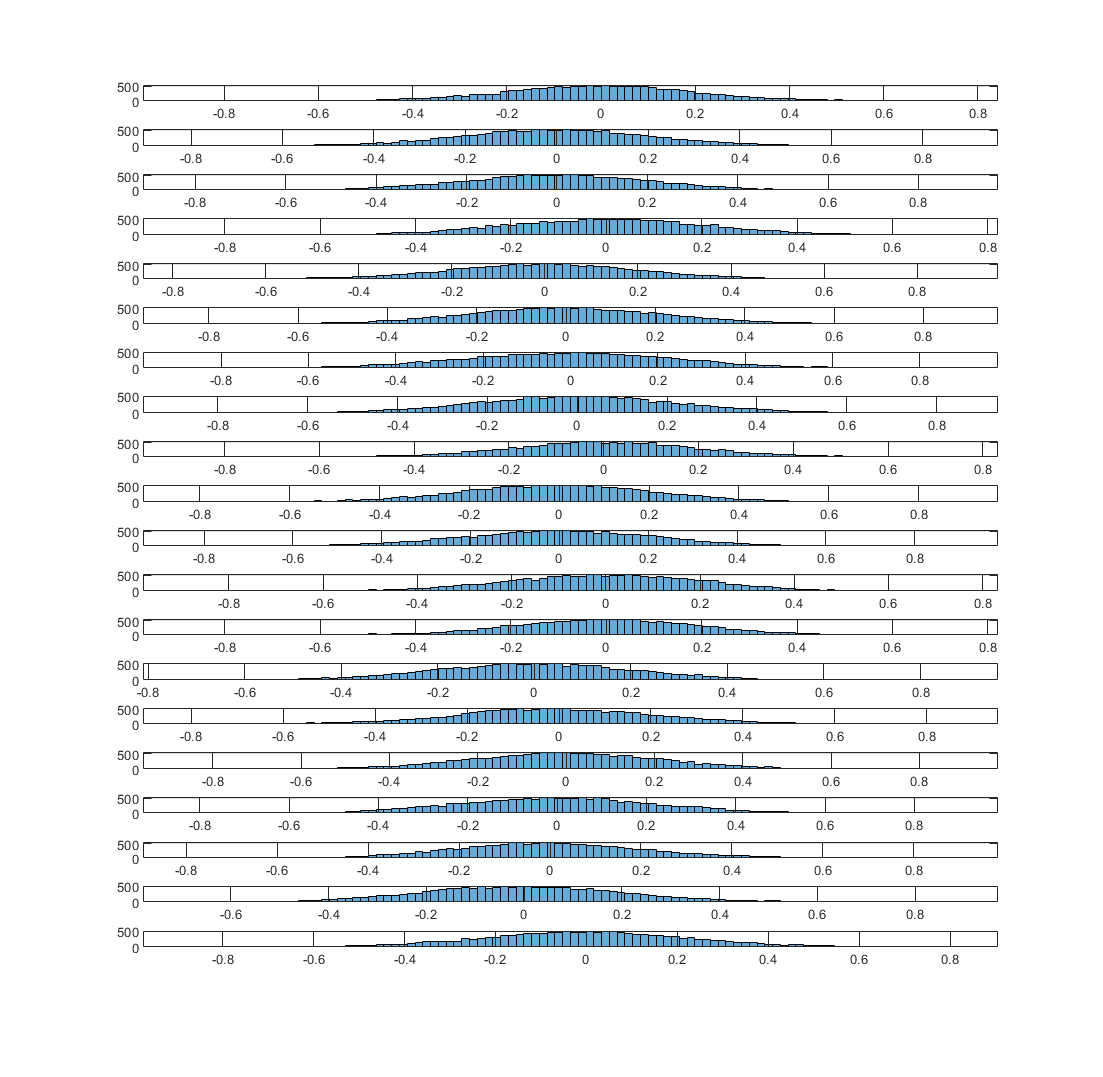

clc;
clear all;
close all;

%-------------------------------------

fan_1sec = ["1sec_audios/fan1.wav","1sec_audios/fan2.wav","1sec_audios/fan3.wav","1sec_audios/fan4.wav","1sec_audios/fan5.wav","1sec_audios/fan6.wav","1sec_audios/fan7.wav","1sec_audios/fan8.wav","1sec_audios/fan9.wav","1sec_audios/fan10.wav","1sec_audios/fan11.wav","1sec_audios/fan12.wav","1sec_audios/fan13.wav","1sec_audios/fan14.wav", "1sec_audios/fan15.wav","1sec_audios/fan16.wav","1sec_audios/fan17.wav","1sec_audios/fan18.wav","1sec_audios/fan19.wav","1sec_audios/fan20.wav"];
nbins = 100;

for x = 1:20
    fan_1sec_data(:,x) = audioread(fan_1sec(x));
end

for x = 1:20
    mean_fan(x) = mean(fan_1sec_data(:,x));
    variance_fan(x) = var(fan_1sec_data(:,x));
    skewness_fan(x) = skewness(fan_1sec_data(:,x));
    kurtosis_fan(x) = kurtosis(fan_1sec_data(:,x));
end
figure1=figure('Position', [0, 0, 1024, 1000]);
for x = 1:20
    subplot(20,1,x);
    histogram(fan_1sec_data(:,x),nbins);
    grid on;
end

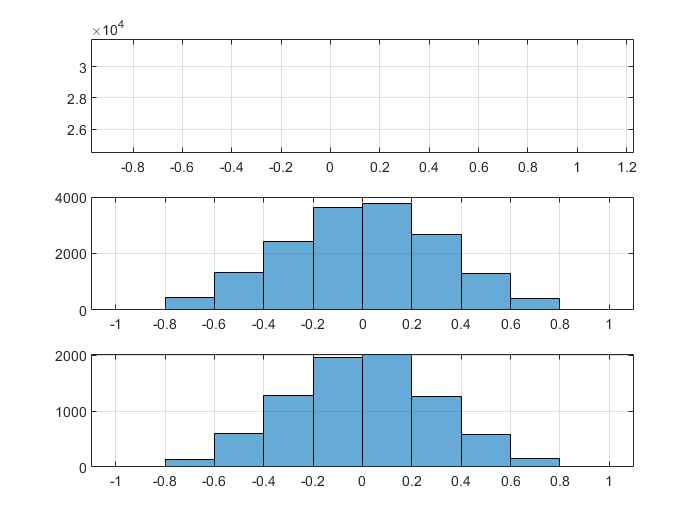

clc;
clear all;
close all;

%-------------------------------------

file1='train/train_1s.wav';
file2='train/train_500ms.wav';
file3='train/train_250ms.wav';
nbins=10;

[train_1s,fs2]=audioread(file1);
[train_500ms,fs2]=audioread(file2);
[train_250ms,fs2]=audioread(file3);

subplot(3,1,1);
a=histogram(train_1s,nbins,'BinWidth',0.2);
grid on;

subplot(3,1,2);
b=histogram(train_500ms,nbins,'BinWidth',0.2);
grid on;

subplot(3,1,3);
c=histogram(train_250ms,nbins,'BinWidth',0.2);
grid on;

mul = 0;
for x = 1:10
    mid(x) = (a.BinEdges(x) + a.BinEdges(x+1))/2;
    mul = mul + mid(x).*a.Values(x);
end
mean = mul/16000;

mul1 = 0;
for x = 1:10
    mid1(x) = (b.BinEdges(x) + b.BinEdges(x+1))/2;
    mul1 = mul1 + mid1(x).*b.Values(x);
end
mean1 = mul1/16000;

mul2 = 0;
for x = 1:10
    mid2(x) = (c.BinEdges(x) + c.BinEdges(x+1))/2;
    mul2 = mul2 + mid2(x).*c.Values(x);
end
mean2 = mul2/16000;